# Función de trasnferencia

Cálculo de función de transferencia a partir de los principios fundamentales del sistema a modelar.

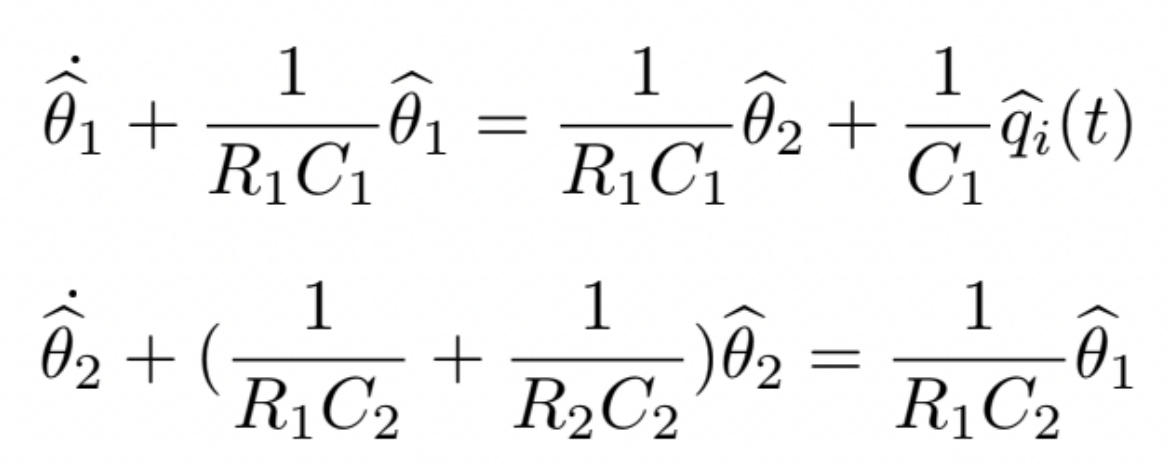

% Definición de ecuaciones 
syms s theta1 theta2 R1 C1 R2 C2 Qi

eq1 = s * theta1 + 1/(R1 * C1) * theta1 == 1/(R1 * C1) * theta2 + 1/C1 * Qi

$$eq1 = s\,\theta_{1}+\frac{\theta_{1}}{C_{1}\,R_{1}}=\frac{\mathrm{Qi}}{C_{1}}+\frac{\theta_{2}}{C_{1}\,R_{1}}$$

eq2 = s * theta2 + ((R1 + R2)/(R1*R2*C2))*theta2 == 1/(R1 * C2) * theta1

$$eq2 = s\,\theta_{2}+\frac{\theta_{2}\,\left(R_{1}+R_{2}\right)}{C_{2}\,R_{1}\,R_{2}}=\frac{\theta_{1}}{C_{2}\,R_{1}}$$

% Solve the equations 
eqs = [eq1 eq2]; 
vars = [Qi, theta1]; 
values = solve(eqs, vars)

values = struct with fields:
        Qi: [1×1 sym]
    theta1: [1×1 sym]


G = simplify(values.theta1 / values.Qi, "Steps", 50); 
G = simplifyFraction(G); 

G

$$G = \frac{R_{1}+R_{2}+C_{2}\,R_{1}\,R_{2}\,s}{C_{1}\,R_{1}\,s+C_{1}\,R_{2}\,s+C_{2}\,R_{2}\,s+C_{1}\,C_{2}\,R_{1}\,R_{2}\,s^{2}+1}$$

# Modelo dinámico 

R1 = 1; 
R2 = 1; 
C1 = 1; 
C2 = 1;

Gl = tf([R1 * R2 * C2, R1 + R2], [C1 * C2 * R1 * R2, C1*R2 + C2*R2 + C1 * R1, 1])

Gl =
 
      s + 2
  -------------
  s^2 + 3 s + 1
 
Continuous-time transfer function.



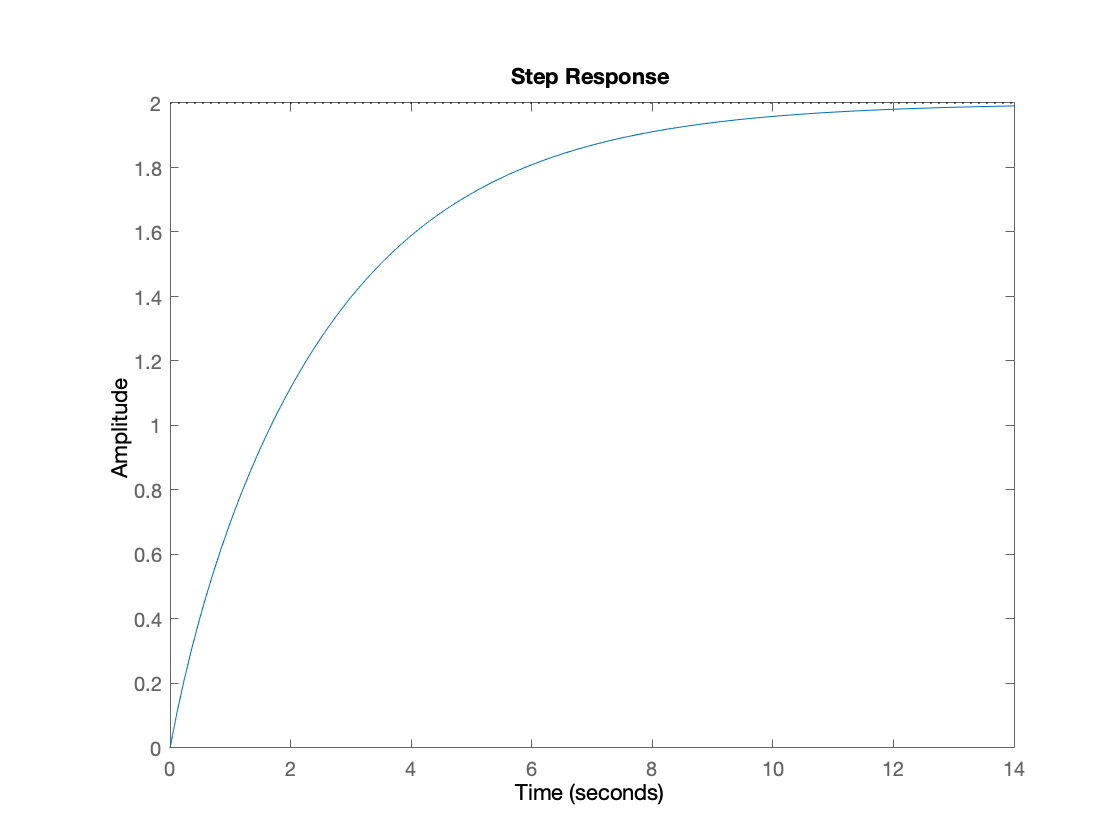

step(Gl)

s = tf('s'); 
Cs = 1/s * 2

Cs =
 
  2
  -
  s
 
Continuous-time transfer function.



Go = feedback(Cs * Gl, 1)

Go =
 
         2 s + 4
  ---------------------
  s^3 + 3 s^2 + 3 s + 4
 
Continuous-time transfer function.



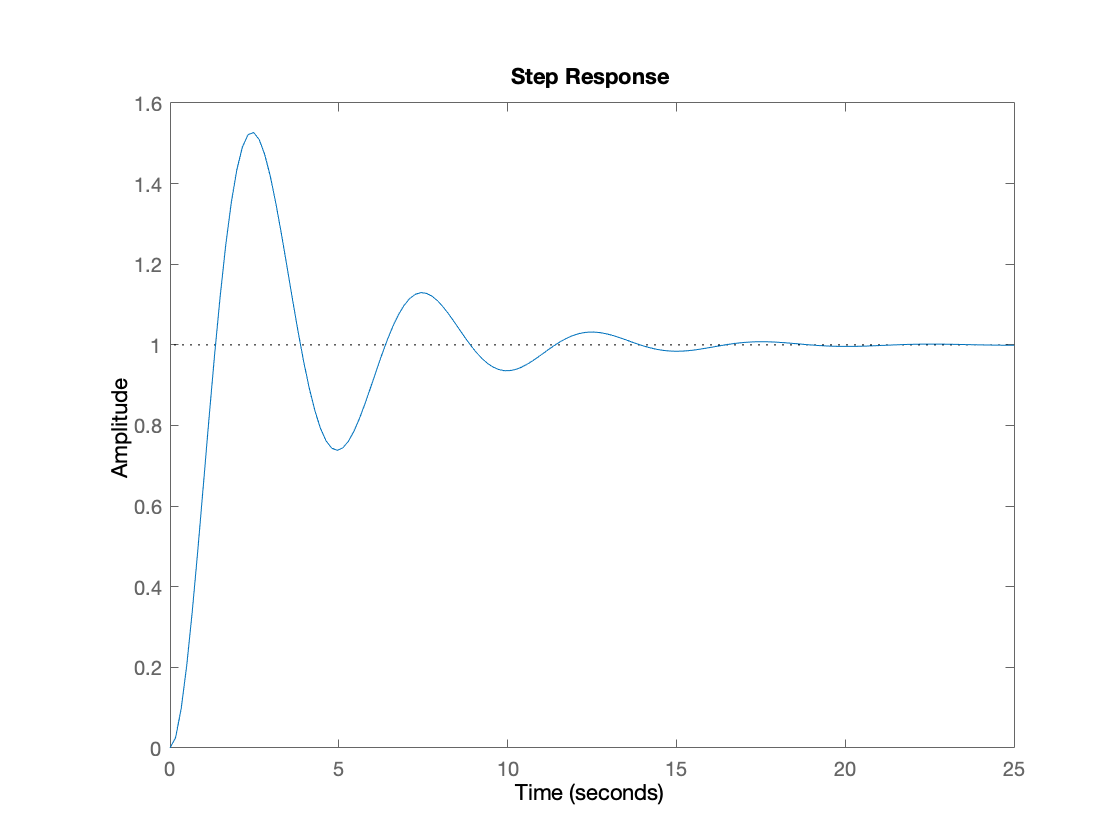

step(Go)

Gl = tf([2 10], [1, 3, 10])

Gl =
 
     2 s + 10
  --------------
  s^2 + 3 s + 10
 
Continuous-time transfer function.



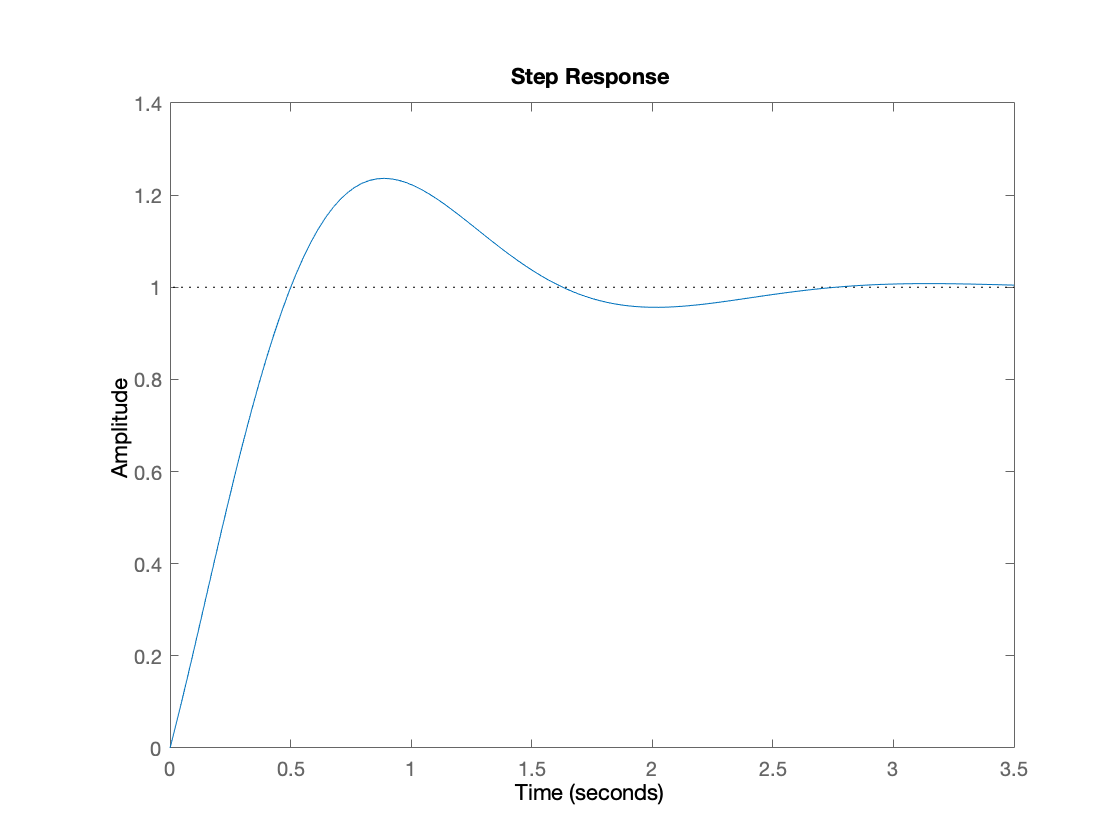

step(Gl)